cAMPFreSimulation

周期不同占空比光信号刺激bPAC生产cAMP，调控下游基因表达

Shuai Yang 2023/2/10

### % 参数定义

% 参数定义
% k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
k = 0.0045;% uM/s
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
T = 1000;% 信号输入的周期 s
P = 0.1;% 占空比
dt = 0.1;% delt t 分割的时间间隔 0.1s
stopTime = 2000;% 模拟的停止时间 s

### % 分析cAMP 浓度变化 

考虑bPAC按恒定速率beta失活


$$x_{Middle} = \frac{\frac{k}{\beta-\gamma}(e^{-\gamma T}-e^{-\beta T+\beta TP -\gamma TP})+\frac{k}{\gamma}(1-e^{-\gamma TP})}{1-e^{-\gamma T}}$$



$$x_{Low} = x_{Middle}e^{-\gamma (T-TP)}+\frac{k}{\beta-\gamma}(e^{-\gamma (T-TP)}-e^{-\beta (T-TP)})$$



$$x(t) =
\begin{cases}
\frac{{\gamma x_{Low}-k}}{\gamma}e^{-\gamma t}+\frac{k}{\gamma},  &&  0\le t\le TP & \\[2ex]
(x_{Middle}-\frac{k}{\gamma-\beta})e^{-\gamma (t-TP)}+\frac{k}{\gamma-\beta}e^{-\beta (t-TP)},  &&  TP< t\le T & \\[2ex]
\end{cases}$$


t_lag = 0:dt:T;
x = NaN(size(t_lag));

x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
    +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
x_Low = x_Mid*exp(-gamma*(T-T*P))...
    +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

n = 0;
for it = 0:dt:T
    n = n+1;
    if it <= T*P
        x(n) = (x_Low-k/gamma)*exp(-gamma*it)+k/gamma;
    else
        x(n) = (x_Mid+k/(beta-gamma))*exp(-gamma*(it-T*P))...
            -k/(beta-gamma)*exp(-beta*(it-T*P));
    end
end
TF = t_lag <= T*P;
figure,
plot(t_lag(TF),x(TF),'Color',[0,0,1],'LineWidth',2);
hold on,
plot(t_lag(~TF),x(~TF),'Color',[0,0,0],'LineWidth',2);

### %批量分析不同后期 cAMP 浓度变化 

Tset = [100,200,400,600,800,1000,1200,1600,1800,2400];
f1 = figure;
ax1 = axes('Parent',f1);
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    t_lag = 0:dt:T;
    x = NaN(size(t_lag));

    x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
        +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
    x_Low = x_Mid*exp(-gamma*(T-T*P))...
        +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

    n = 0;
    for it = 0:dt:T
        n = n+1;
        if it <= T*P
            x(n) = (x_Low-k/gamma)*exp(-gamma*it)+k/gamma;
        else
            x(n) = (x_Mid+k/(beta-gamma))*exp(-gamma*(it-T*P))...
                -k/(beta-gamma)*exp(-beta*(it-T*P));
        end
    end
    TF = t_lag <= T*P;

    t_New = (2500-t_lag(end))+t_lag;% 末尾点对齐
    plot(t_New(TF),x(TF),'Color',[0,0,1],'LineWidth',1.5);
    hold on,
    plot(t_New(~TF),x(~TF),'Color',[0,0,0],'LineWidth',1.5);
end
xlabel(ax1,'time (s)')
ylabel(ax1,'cAMP Conc. (uM)')

### %批量分析TF_DNA变化   beta bPAC按照一定速率失活

cAMP与Vfr结合形成Vfr-cAMP2，进一步形成TF_DNA

% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM

Vfr = 0.27;% uM TF因子数目
DNA = 0.05; % uM 启动子的DNA数目

lambda = Vfr/K2;
% TF_DNA = p_DNA*(lambda/((1+lambda)+1/x^2));

Tset = [50,100,200,400,600,800,1000,1200,1600,1800,2400];

f1 = figure;
% ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
subplt2 = subplot(2,1,2,'Parent',f1);
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    t_lag = 0:dt:T;
    x = NaN(size(t_lag));
    TF_DNA = NaN(size(t_lag));

    x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
        +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
    x_Low = x_Mid*exp(-gamma*(T-T*P))...
        +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

    n = 0;
    for it = 0:dt:T
        n = n+1;
        if it <= T*P
            x(n) = (x_Low-k/gamma)*exp(-gamma*it)+k/gamma;

        else
            x(n) = (x_Mid+k/(beta-gamma))*exp(-gamma*(it-T*P))...
                -k/(beta-gamma)*exp(-beta*(it-T*P));
        end
        x1 = x(n)/K1;
        TF_DNA(n) = DNA*(lambda/((1+lambda)+1/x1^2));
    end
    TF = t_lag <= T*P;
    t_New = (2500-t_lag(end))+t_lag;% 末尾点对齐

    hold(subplt1,'on');
    plot(t_New(TF),x(TF),'Color',[0,0,1],'LineWidth',1.5,'Parent',subplt1);
    plot(t_New(~TF),x(~TF),'Color',[0,0,0],'LineWidth',1.5,'Parent',subplt1);
    hold(subplt1,'off');

    hold(subplt2,'on');
    plot(t_New(TF),TF_DNA(TF),'Color',[0,0,1],'LineWidth',2,'Parent',subplt2);
    plot(t_New(~TF),TF_DNA(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt2);
    hold(subplt2,'off');

end

set(subplt1,'Tickdir','out','Box','off','FontSize',12);
set(subplt2,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'cAMP Conc. (uM)')

xlabel(subplt2,'time (s)')
ylabel(subplt2,'TF_DNA (uM)','Interpreter','none')


### %批量分析TF_DNA变化   beta bPAC瞬间失活

cAMP与Vfr结合形成Vfr-cAMP2，进一步形成TF_DNA

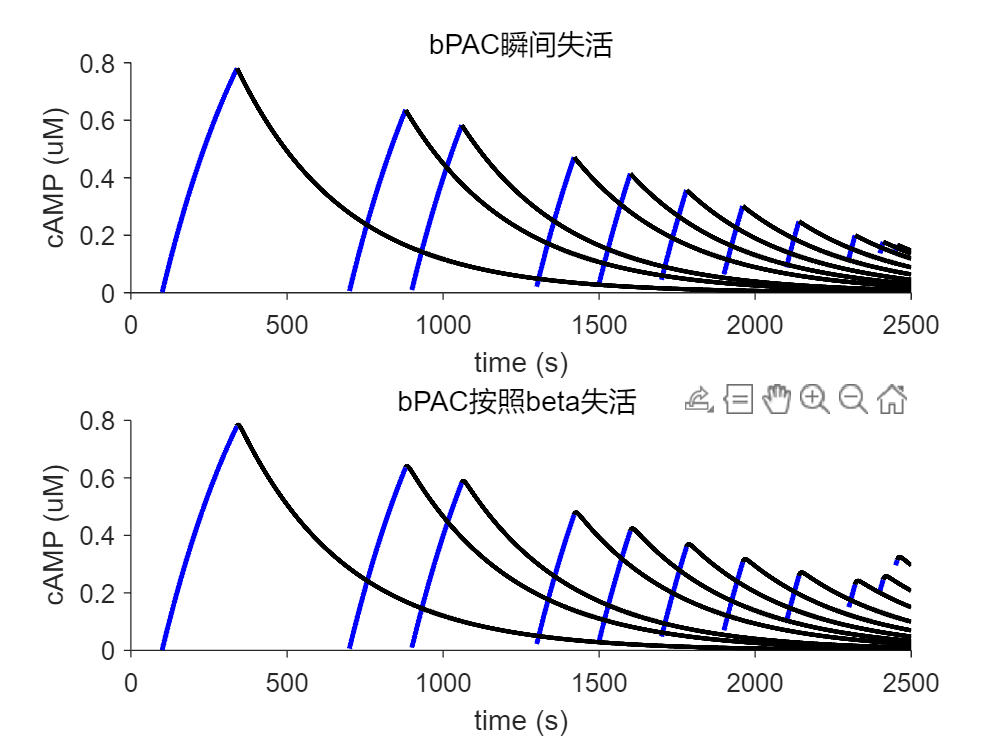

k = 0.0045;% uM/s
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
P = 0.1;% 占空比

% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM

Vfr = 0.27;% uM TF因子数目
DNA = 0.05; % uM 启动子的DNA数目

lambda = Vfr/K2;
% TF_DNA = p_DNA*(lambda/((1+lambda)+1/x^2));

Tset = [50,100,200,400,600,800,1000,1200,1600,1800,2400];
dt = 0.1;
f1 = figure;
% ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
subplt2 = subplot(2,1,2,'Parent',f1);
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    t_lag = 0:dt:T;


    x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
    x_Low = x_High*exp(-gamma*(T-T*P));
    t = 0:dt:T;
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_High*exp(-gamma*(t-T*P))).*(t>T*P);




    TF = t_lag <= T*P;
    t_New = (2500-t_lag(end))+t_lag;% 末尾点对齐



    hold(subplt1,'on');
    plot(t_New(TF),x(TF),'Color',[0,0,1],'LineWidth',2,'Parent',subplt1);
    plot(t_New(~TF),x(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt1);
    hold(subplt1,'off');

    x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
        +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
    x_Low = x_Mid*exp(-gamma*(T-T*P))...
        +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

    x1 = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        ((x_Mid+k/(beta-gamma))*exp(-gamma*(t-T*P)) ...
        -k/(beta-gamma)*exp(-beta*(t-T*P))).*(t>T*P);

    hold(subplt2,'on');
    plot(t_New(TF),x1(TF),'Color',[0,0,1],'LineWidth',2,'Parent',subplt2);
    plot(t_New(~TF),x1(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt2);
    hold(subplt2,'off');

end

set(subplt1,'Tickdir','out','Box','off','FontSize',10);
set(subplt2,'Tickdir','out','Box','off','FontSize',10);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'cAMP (uM)','Interpreter','none')
title(subplt1,'bPAC瞬间失活')

xlabel(subplt2,'time (s)')
ylabel(subplt2,'cAMP (uM)','Interpreter','none')
title(subplt2,'bPAC按照beta失活 ')

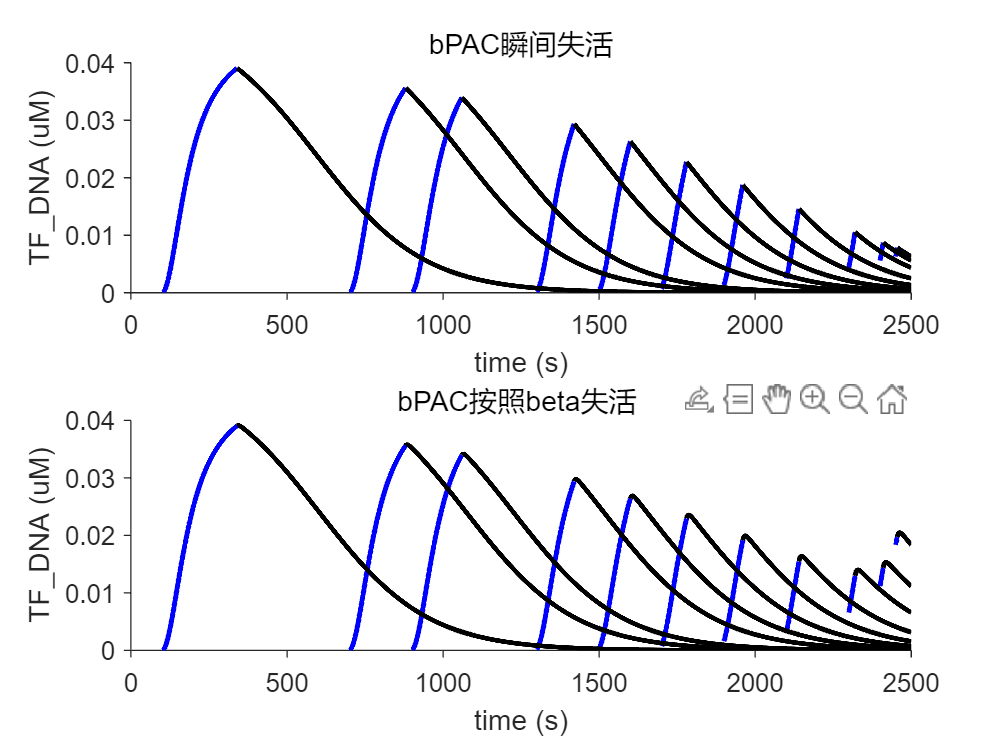



Tset = [50,100,200,400,600,800,1000,1200,1600,1800,2400];
dt = 0.1;
f1 = figure;
% ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
subplt2 = subplot(2,1,2,'Parent',f1);
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    t_lag = 0:dt:T;


    x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
    x_Low = x_High*exp(-gamma*(T-T*P));
    t = 0:dt:T;
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

    x1 = x/K1;
    TF_DNA = DNA*lambda./((1+lambda)+1./x1.^2);
    u = cAMPOutPut(t,T);
    u = DNA*u; %与按照beta失活情况比较 DNA



    TF = t_lag <= T*P;
    t_New = (2500-t_lag(end))+t_lag;% 末尾点对齐



    hold(subplt1,'on');
    plot(t_New(TF),TF_DNA(TF),'Color',[0,0,1],'LineWidth',2,'Parent',subplt1);
    plot(t_New(~TF),TF_DNA(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt1);
    hold(subplt1,'off');

    hold(subplt2,'on');
    plot(t_New(TF),u(TF),'Color',[0,0,1],'LineWidth',2,'Parent',subplt2);
    plot(t_New(~TF),u(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt2);
    hold(subplt2,'off');

end

set(subplt1,'Tickdir','out','Box','off','FontSize',10);
set(subplt2,'Tickdir','out','Box','off','FontSize',10);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'TF_DNA (uM)','Interpreter','none')
title(subplt1,'bPAC瞬间失活')

xlabel(subplt2,'time (s)')
ylabel(subplt2,'TF_DNA (uM)','Interpreter','none')
title(subplt2,'bPAC按照beta失活 ')

### % cAMP浓度对稳定基因表达的影响

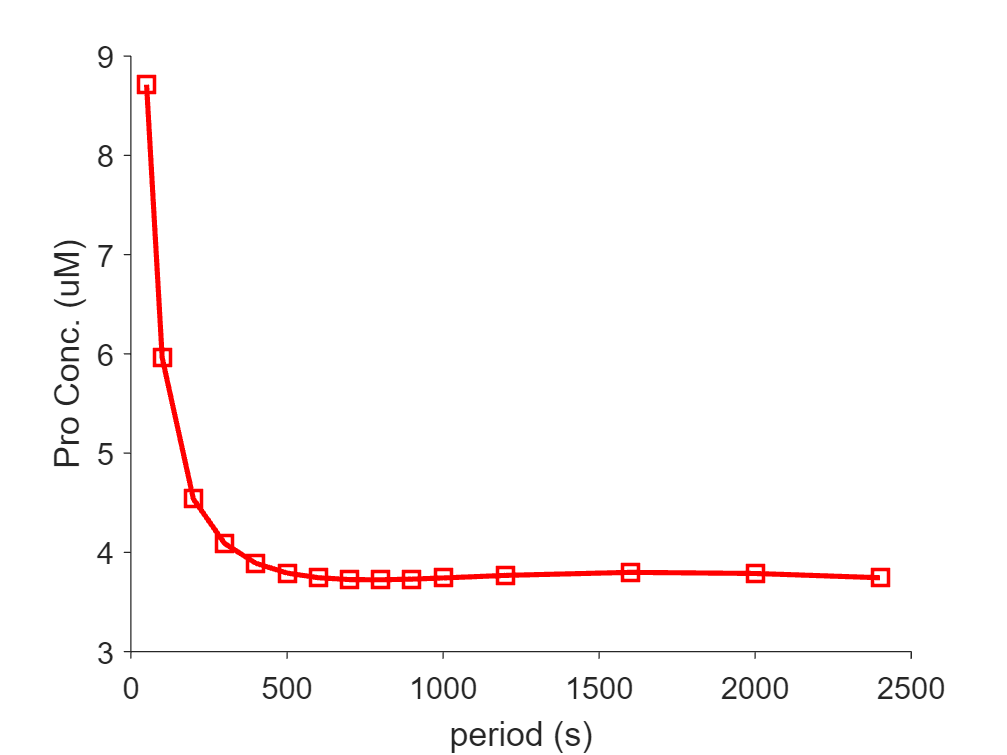

gamma2 = 2.7e-4;  %蛋白的降解率 s-1
k2 = 0.12 ;% s-1 蛋白生产率 = 转录率*翻译率/mRNA降解率 = 0.02*0.03/0.005
ymax = k2/gamma2*DNA;% 蛋白的最大表达量 uM

% fun = @(t) ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
%     ((x_Mid+k/(beta-gamma))*exp(-gamma*(t-T*P)) ...
%     -k/(beta-gamma)*exp(-beta*(t-T*P))).*(t>T*P);

Tset = [50,100:100:1000,1200:400:2400];
% xTickNames = string(Tset);
y = NaN(size(Tset));
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    fun =@(t,T) cAMPOutPut(t,T);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;
    y(iPeroid) = q1;
end

% f1 = figure;
% ax1 = axes('Parent',f1);
% bar1 = bar(y*ymax);
% xlabel(ax1,'period (s)')
% ylabel(ax1,'Pro conC. (uM)')
% set(ax1,'Tickdir','out','Box','off');
% set(ax1,'FontSize',12,'XTick',[1:numel(y)],'XTickLabel',...
%     xTickNames,'TickLabelInterpreter','none');

f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,y*ymax,'Marker','square','MarkerSize',8,'Color','r','LineWidth',2);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'period (s)')
ylabel(ax1,'Pro Conc. (uM)')

% 与取波峰和波谷的平均值进行比较

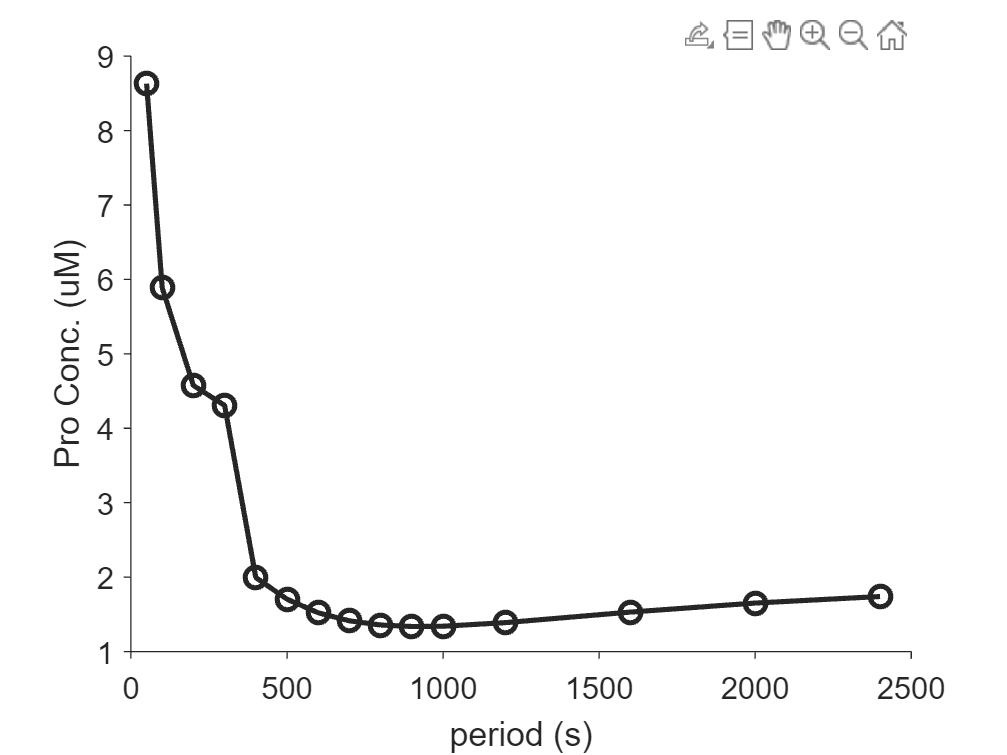


Tset = [50,100:100:1000,1200:400:2400];

y = NaN(size(Tset));
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
        +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
    x_Low = x_Mid*exp(-gamma*(T-T*P))...
        +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));
    Dn = 1/(gamma-beta)*log(gamma*(x_Mid*(beta-gamma)-k)/(beta*k));
    x_High = (x_Mid+k/(beta-gamma))*exp(-gamma*Dn)-k/(beta-gamma)*exp(-beta*Dn);

    x_Low1 = x_Low/K1;
    x_High1 = x_High/K1;

    y_Low = lambda./((1+lambda)+1./x_Low1.^2);
    y_High = lambda./((1+lambda)+1./x_High1.^2);

    % y(iPeroid) = (y_Low+y_High)/2;
    % 重新近似 式11
    if T < 1/gamma
        y(iPeroid) = (y_Low+y_High)/2;
    else
        y(iPeroid) = P*(y_High-y_Low)+y_Low;
    end

end
f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,y*ymax,'Marker','o','MarkerSize',8,'Color',[0.15,0.15,0.15],'LineWidth',2);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'period (s)')
ylabel(ax1,'Pro Conc. (uM)')

无量纲化分析 考虑bPAC瞬间失活 

% k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
k = 0.0045;% uM/s
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
% T = 1000;% 信号输入的周期 s
P = 0.1;% 占空比
dt = 0.1;% delt t 分割的时间间隔 0.1s
%%
% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM
Vfr = 0.27;% uM TF因子数目
DNA = 0.05; % uM 启动子的DNA数目
lambda = Vfr/K2;




Tset = [50,100:100:1000,1200:400:2400];
% xTickNames = string(Tset);
y_output1 = NaN(size(Tset));
y_output2 = NaN(size(Tset));
y_output3 = NaN(size(Tset));
x_HL = NaN(2,numel(Tset));
s_HL = NaN(2,numel(Tset));

for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid); 

    x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
    x_Low = x_High*exp(-gamma*(T-T*P));

    t = 0:dt:T;
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

    a = k/gamma;
    phi = gamma*T;
    tao = gamma*t;

    % sH = x_High/a;
    % sL = x_Low/a;

    sH = (1-exp(-phi*P))/(1-exp(-phi));
    sL = (exp(phi*P)-1)/(exp(phi)-1);

    dtao = dt*gamma;
    s_tao = (1-(1-sL)*exp(-tao)).*(tao<=phi*P)+...
        (sH*exp(-tao+phi*P)).*(tao>phi*P);

    % 验证
    % figure,plot(x);hold on,plot(s_tao*a);% 两条曲线重合

    theta = lambda*(a/K1)^2;
    alpha = k/(gamma*K1);



    % 针对 lambda远远大于1 的近似情况 瞬间失活的 积分
    y = (1/phi)*((theta/(1+theta)*log((1-sL)*sqrt(1+theta*(sH)^2)/((1-sH)*sqrt(1+theta*(sL)^2))))- ...
        (sqrt(theta)/(1+theta)*atan(sqrt(theta)*(sH-sL)/(1+theta*sL*sH))));


    sH1 = sinh(phi*P/2)/sinh(phi/2)*exp(phi*(1-P)/2);
    sL1 = sinh(phi*P/2)/sinh(phi/2)*exp(-phi*(1-P)/2);

    testP = 1/phi*log((1-sL)/(1-sH));

    y_test = (1/phi)*((theta/(1+theta)*log(sqrt(1+theta*(sH)^2)/sqrt(1+theta*(sL)^2)))- ...
        (sqrt(theta)/(1+theta)*atan(sqrt(theta)*(sH-sL)/(1+theta*sL*sH))))+theta*P/(1+theta);


    % 不针对 lambda大于1 进行近似
    y1 = (1/phi)*((lambda*alpha^2/(1+(lambda+1)*alpha^2))*log(sqrt(1+(lambda+1)*alpha^2*sH^2)/sqrt(1+(lambda+1)*alpha^2*sL^2))-...
        alpha*lambda/sqrt(lambda+1)/(1+(lambda+1)*alpha^2)*atan(alpha*sqrt(lambda+1)*(sH-sL)/(1+(lambda+1)*alpha^2*sL*sH)))+...
        lambda*alpha^2*P/(1+(lambda+1)*alpha^2);

    x1 = x/K1;
    u = lambda./((1+lambda)+1./x1.^2);
    u1 = cAMPOutPut1(t,T);

    fun =@(t,T) cAMPOutPut1(t,T);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;

    y_output1(iPeroid) = q1;% 数值积分
    y_output2(iPeroid) = y; % bPAC 瞬间失活 针对λ远大于1的近似
    y_output3(iPeroid) = y1;% bPAC 瞬间失活 一般情况未近似

    x_HL(1,iPeroid) = x_High;
    x_HL(2,iPeroid) = x_Low;
    s_HL(1,iPeroid) = sH1;
    s_HL(2,iPeroid) = sL1;

end

f1 = figure;

f1 =   Figure (7) - 属性:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [467 311 560 420]
       Units: 'pixels'

  显示 所有属性


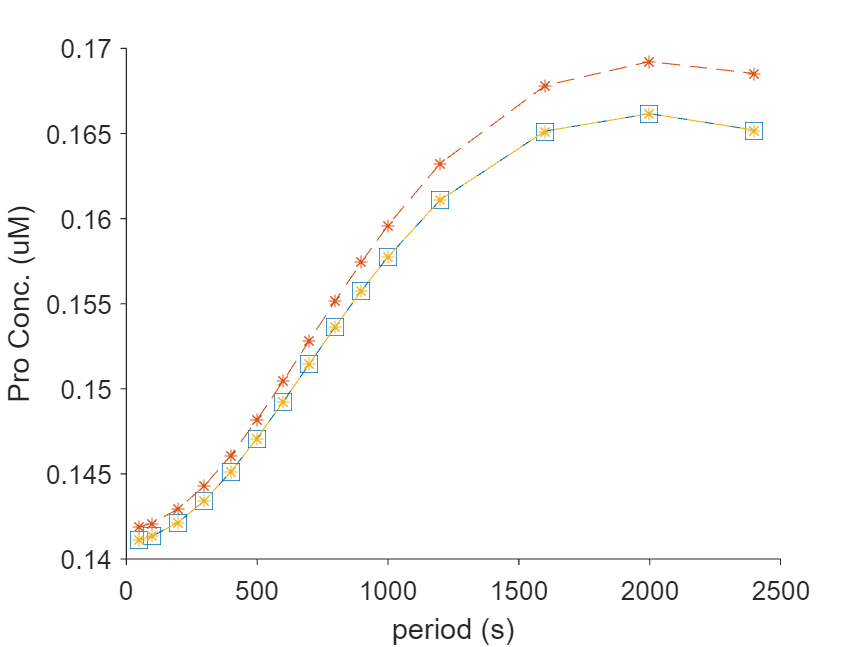

ax1 = axes('Parent',f1);
plot(Tset,y_output1,'Marker','square','MarkerSize',10)
hold on,plot(Tset,y_output2,'LineStyle','--','Marker','*')
hold on,plot(Tset,y_output3,'LineStyle','--','Marker','*')

set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'period (s)')
ylabel(ax1,'Pro Conc. (uM)')


f1 = figure;

f1 =   Figure (8) - 属性:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [467 311 560 420]
       Units: 'pixels'

  显示 所有属性


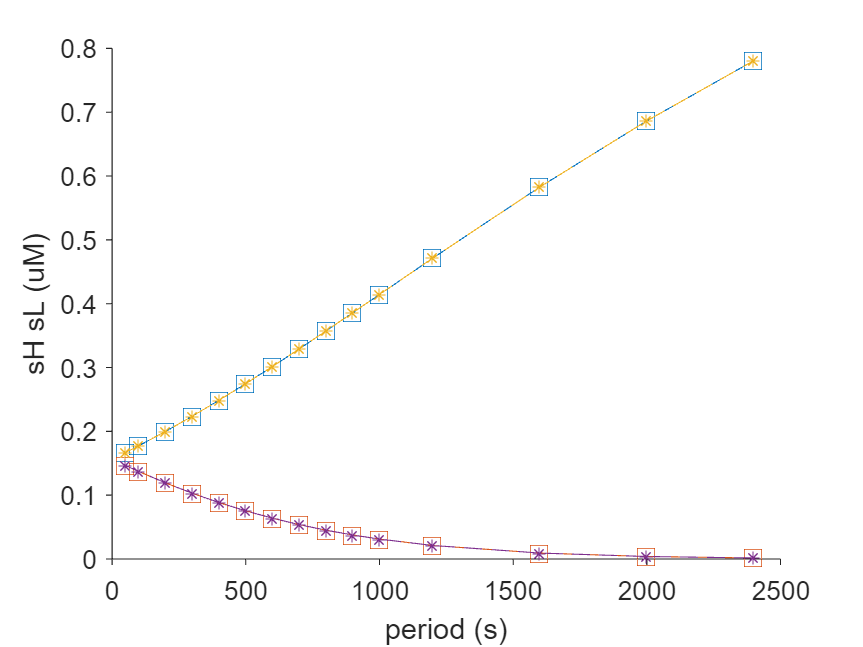

ax1 = axes('Parent',f1);
plot(Tset,x_HL,'Marker','square','MarkerSize',10)
hold on,plot(Tset,s_HL*a,'LineStyle','--','Marker','*')
% hold on,plot(Tset,y_output3,'LineStyle','--','Marker','*')

set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'period (s)')
ylabel(ax1,'sH sL (uM)')

考虑bPAC不是瞬间失活的情况 有beta的存在

Tset = [50,100:100:1000,1200:400:2400];

gamma2 = 2.7e-4;  %蛋白的降解率 s-1
k2 = 0.12 ;% s-1 蛋白生产率 = 转录率*翻译率/mRNA降解率 = 0.02*0.03/0.005
ymax = k2/gamma2*DNA;% 蛋白的最大表达量 uM

% xTickNames = string(Tset);
y_output1 = NaN(size(Tset));
y_output2 = NaN(size(Tset));
y_output3 = NaN(size(Tset));
for iPeroid = 1:numel(Tset)
    

    % k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
    k = 0.0045;% uM/s
    gamma = 0.002876;% s-1,cAMP被降解的速率
    beta = 0.2; %s-1, bPAC失去活性的速率
    % T = 1000;% 信号输入的周期 s
    P = 0.1;% 占空比
    dt = 0.1;% delt t 分割的时间间隔 0.1s
    %%
    % cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
    n1 = 2; %
    K1 = 2; % uM
    % Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
    n2 = 1; %
    K2 = 0.01; % 0.01uM = 10nM
    Vfr = 0.27;% uM TF因子数目
    DNA = 0.05; % uM 启动子的DNA数目
    lambda = Vfr/K2;

    T = Tset(iPeroid);
    fun =@(t,T) cAMPOutPut(t,T);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;

    x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
    x_Low = x_High*exp(-gamma*(T-T*P));

    t = 0:dt:T;
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

    a = k/gamma;
    phi = gamma*T;
    tao = gamma*t;
    b =  gamma/beta;% 如果瞬间失活 b = 0；

    % sH = x_High/a;
    % sL = x_Low/a;


    sH = (((1-exp(-phi*P))+b*exp(-phi*P)*(1-exp(-phi*(1-P)/b)))/(1-exp(-phi)))^(1/(1-b));
    sL = ((exp(-phi*P)-1)+b*(1-exp(-phi*(1-b-P)/b)))/((exp(phi)-1)*(1-b));

    % 近似 b 远远小于1
    sH1 = ((1-exp(-phi*P))+b*exp(-phi*P)*(1-exp(-phi*(1-P)/b)))/(1-exp(-phi));
    sL1 = ((exp(-phi*P)-1)+b*(1-exp(-phi*(1-P)/b)))/(exp(phi)-1);


    dtao = dt*gamma;
    s_tao = (1-(1-sL)*exp(-tao)).*(tao<=phi*P)+...
        (sH*exp(-tao+phi*P)).*(tao>phi*P);

    % 验证
    % figure,plot(x)；hold on,plot(s_tao*a)；% 两条曲线重合

    theta = lambda*(a/K1)^2;
    alpha = k/(gamma*K1);


    % 积分解析解
    y = (1/phi)*((lambda*alpha^2/(1+(lambda+1)*alpha^2))*log(sqrt(1+(lambda+1)*alpha^2*sH^2)/sqrt(1+(lambda+1)*alpha^2*sL^2))-...
        alpha*lambda/sqrt(lambda+1)/(1+(lambda+1)*alpha^2)*atan(alpha*sqrt(lambda+1)*(sH-sL)/(1+(lambda+1)*alpha^2*sL*sH)))+...
        lambda*alpha^2*P/(1+(lambda+1)*alpha^2);

    x1 = x/K1;
    u = lambda./((1+lambda)+1./x1.^2);


    y_output1(iPeroid) = q1;
    y_output2(iPeroid) = y;


end

f1 = figure,

f1 =   Figure (5) - 属性:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [817 612 560 420]
       Units: 'pixels'

  显示 所有属性


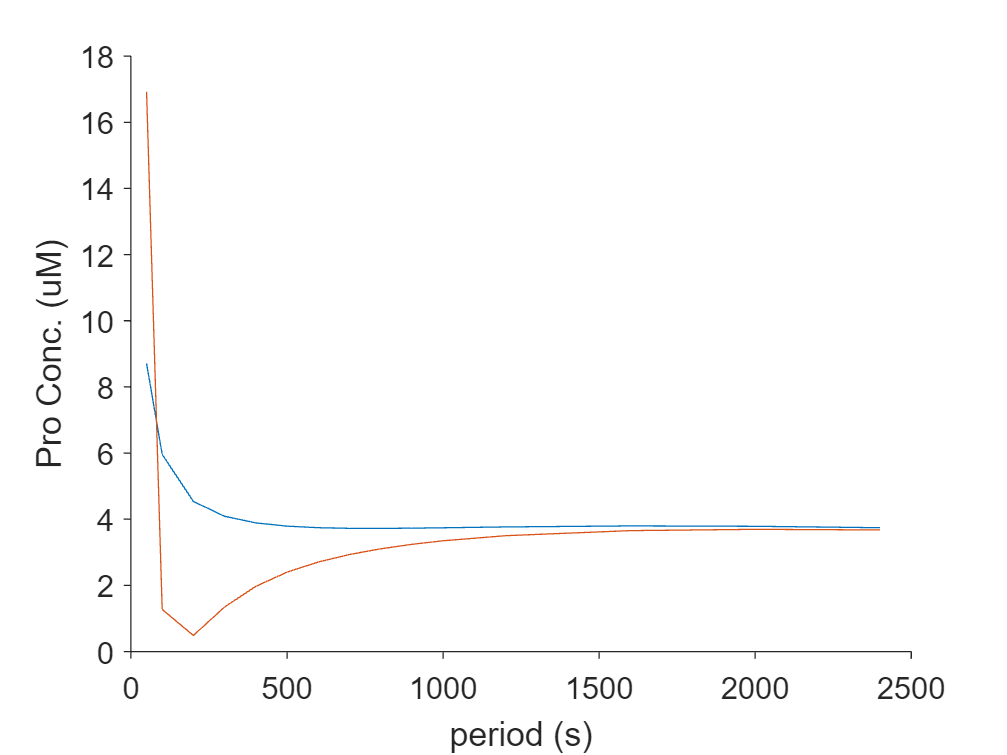

ax1 = axes('Parent',f1);
plot(Tset,y_output1*ymax)
hold on,plot(Tset,y_output2*ymax)

set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'period (s)')
ylabel(ax1,'Pro Conc. (uM)')

function u = cAMPOutPut(t,T)
% t 时间 T 周期
%%  参数定义
% k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
k = 0.0045;% uM/s
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
% T = 1000;% 信号输入的周期 s
P = 0.1;% 占空比
dt = 0.1;% delt t 分割的时间间隔 0.1s
%%
% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM
Vfr = 0.27;% uM TF因子数目
DNA = 0.05; % uM 启动子的DNA数目
lambda = Vfr/K2;

x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
    +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
x_Low = x_Mid*exp(-gamma*(T-T*P))...
    +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
    ((x_Mid+k/(beta-gamma))*exp(-gamma*(t-T*P)) ...
    -k/(beta-gamma)*exp(-beta*(t-T*P))).*(t>T*P);

x1 = x/K1;
u = lambda./((1+lambda)+1./x1.^2);
end

function u = cAMPOutPut1(t,T)
% 针对 lambda远远大于1 的情况 瞬间失活的情况 beta的事情
% t 时间 T 周期
%%  参数定义
% k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
k = 0.0045;% uM/s
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
% T = 1000;% 信号输入的周期 s
P = 0.1;% 占空比
dt = 0.1;% delt t 分割的时间间隔 0.1s
%%
% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM
Vfr = 0.27;% uM TF因子数目
DNA = 0.05; % uM 启动子的DNA数目
lambda = Vfr/K2;

x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
x_Low = x_High*exp(-gamma*(T-T*P));

x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
    (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

x1 = x/K1;
u = lambda./((1+lambda)+1./x1.^2);
end